ax = 1/6.18;
ai = 1/6.49;
d = 0.05;
KI0 = 2957654938;
KC0 = 8106067072;
KX0 = 3159000000;

g = @(ex, ax) (ex)/(ax) - d;
%r = @(l, ai) l/ai - d;
r = @(l, ai) l/ai - d;

B = @(ei, ex, l, ax, Kx0) ei/((g(ex, ax) - r(l, ai)).*ax).*Kx0;
A = @(ei, ex, l, ax, Kx0, Ki0) Ki0 - B(ei, ex, l, ax, Kx0);
G = @(ei, ex, ec, l, ax, Kx0) (1 - l)/(ex)*B(ei, ex, l, ax, Kx0) + (ec/ex).*Kx0;
H = @(ei, ex, ec, l, ax, Kx0, Ki0, Kc0) Kc0 - ((1 - l)/l).*A(ei, ex, l, ax, Kx0, Ki0) - G(ei, ex, ec, l, ax, Kx0);

Kc = @(t, ei, ex, ec, l, ax, Kx0, Ki0, Kc0) H(ei, ex, ec, l, ax, Kx0, Ki0, Kc0).*exp(-d.*t) + ((1 - l)/l) .* A(ei, ex, l, ax, Kx0, Ki0).*exp(r(l, ax).*t) + G(ei, ex, ec, l, ax, Kx0).*exp(g(ex, ax)*t);
Kx = @(t, ex, ax, Kx0) Kx0.*exp(g(ex, ax).*t);
Ki = @(t, ei, ex, ec, l, ax, Kx0, Ki0) A(ei, ex, l, ax, Kx0, Ki0).*exp(r(l, ax).*t) + B(ei, ex, l, ax, Kx0).*exp(g(ex, ax).*t);

disp(Kc(0, 0.999999, 0.0000005, 0.0000005, 0.7, 6.49, KX0, KI0, KC0));

   8.1061e+09



disp(Ki(1, 0.9, 0.05, 0.05, 0.7, 6.49, KX0, KI0));

   3.1436e+09



disp(Kx(1, 0.5, 6.49, KX0));

   3.2456e+09



%variables = {'ei', 'ex', 'ec', 'l'};
%N = length(variables); 
% create variables for indexing 
%for v = 1:N 
%   eval([variables{v},' = ', num2str(v),';']); 
%end

axData = [2.365392904 2.447782196 2.549248296 2.577342585 2.59278116 2.846372613 3.049846679 2.993008329 2.984922501 2.824152482 2.931216846 3.053382419 3.245661044 3.295005157 3.412265504 3.256894698 3.355890473 3.300894166 3.291311264 3.641718064 3.570226913 3.509495379 3.538453799 3.447844652 3.460490808 3.424788351 3.418565636 3.454293817 3.301339919 3.273222956 3.287233821 3.399742821 3.384903695 3.373129334 3.304350331 3.230642246 3.156679961 3.196583883 3.182600246 3.130238438 3.191395679];


x0 = [0.01 0.01 0.98 0.5];
options = optimoptions('fmincon','Algorithm','interior-point','Display','iter');

lb = [0 0 0 0];
ub = [1 1 1 1];
Aeq = [1 1 1 0]; 
beq = 1;
%Aeq(1,[ei,ex,ec]) = [1,1,1];

%t = 1
x = [0 0 0 0]

x =      0     0     0     0


fval = 0

fval = 0

optimal = zeros(40,5)

optimal =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


optimal(1,1:4) = [1 1 1 1]

optimal =      1     1     1     1     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


disp(optimal)

     1     1     1     1     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0  

%disp(Kc_op(0.999999, 0.0000005, 0.0000005, 0.7));

KXI = zeros(41,3)

KXI =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


KXI(1,1) = KX0

KXI = 1.0e+09 *

    3.1590         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0


KXI(1,2) = KI0

KXI = 1.0e+09 *

    3.1590    2.9577         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0


KXI(1,3) = KC0

KXI = 1.0e+09 *

    3.1590    2.9577    8.1061
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0



%for t = 1:40
    %KXI(t,1) = Kx(t, optimal(t,2), axData(t+1), KX0);
    %KXI(t,2) = Ki(t, optimal(t,1), optimal(t,2), optimal(t,3), optimal(t,4), axData(t+1), KX0, KI0);
%end

for t = 1:40
    Kc_op = @(x)  (-1).*Kc(t,x(1), x(2), x(3), x(4), axData(t+1), KXI(t,1), KXI(t,2), KXI(t,3));
    %disp(Kc_op([0.5 0.2 0.3 0.5]));
    [y,fval] = fmincon(Kc_op,x0,[],[],Aeq,beq,lb,ub);
    %disp(y)
    %disp(fval)
    optimal(t,1:4) = y;
    optimal(t,5) = -1.*fval;
    KXI(t+1,1) = Kx(t, optimal(t,2), axData(t+1), KX0);
    KXI(t+1,2) = Ki(t, optimal(t,1), optimal(t,2), optimal(t,3), optimal(t,4), axData(t+1), KX0, KI0);
    KXI(t+1,3) = -1.*fval;
    %disp(optimal)
end


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
<a href = "mat


%disp(optimal)
v = [1:40]

v =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40


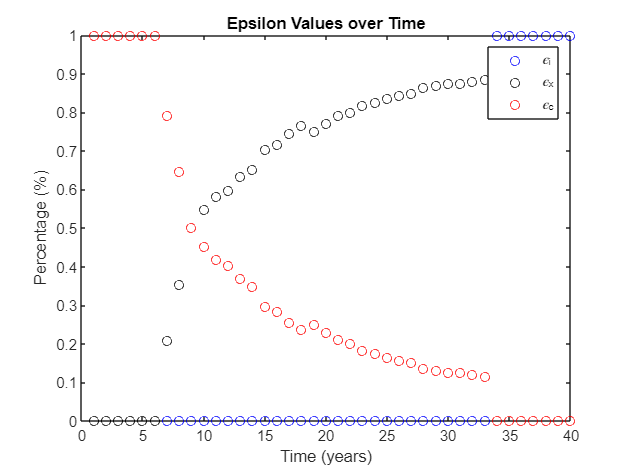

%disp(v)

figure
plot(v,optimal(:,1),'bo',v,optimal(:,2),'ko',v,optimal(:,3),'ro')

title('Epsilon Values over Time')
xlabel('Time (years)')
ylabel('Percentage (%)')
legend('\epsilon_i', '\epsilon_x', '\epsilon_c')
saveas(gcf, "epsilons.png")

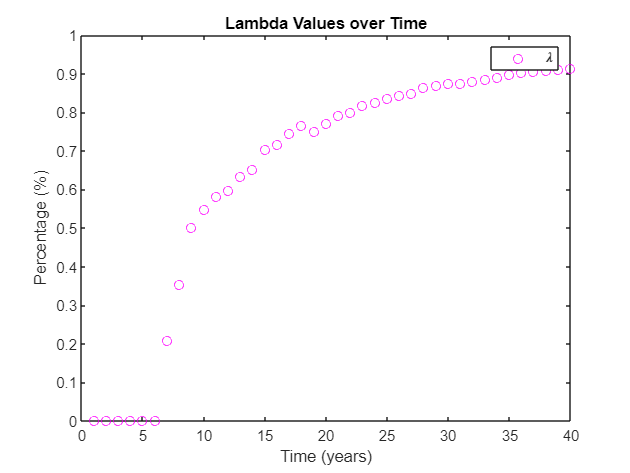


%disp(fval)
figure
plot(v,optimal(:,4),'mo')

title('Lambda Values over Time')
xlabel('Time (years)')
ylabel('Percentage (%)')
legend('\lambda')
saveas(gcf, "lambda.png")

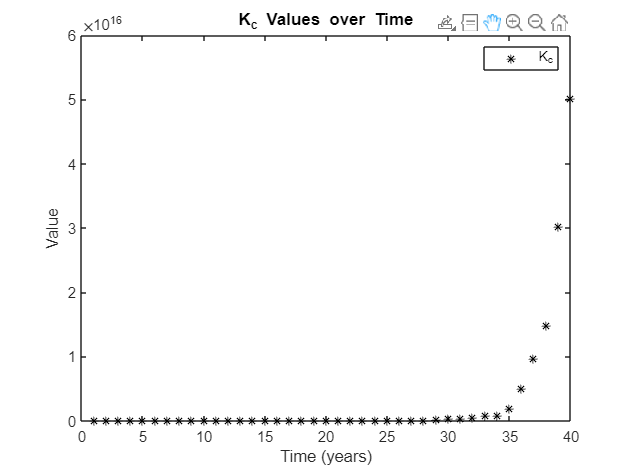



figure
plot(v,optimal(:,5),'k*')

title('K_c Values over Time')
xlabel('Time (years)')
ylabel('Value')
legend('K_c')
saveas(gcf, "kc.png")

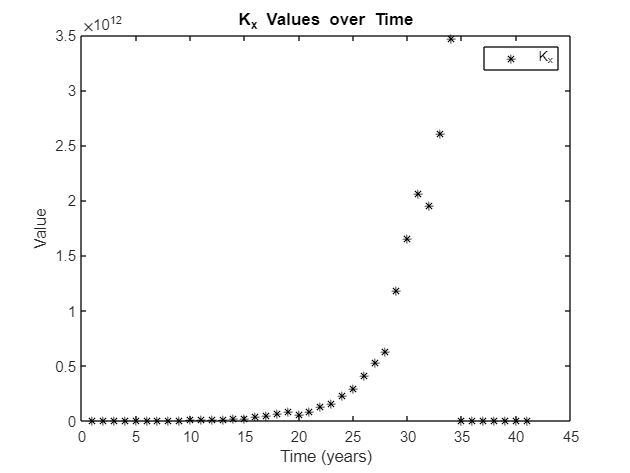



v1 = [1:41];
figure
plot(v1,KXI(:,1),'k*')

title('K_x Values over Time')
xlabel('Time (years)')
ylabel('Value')
legend('K_x')
saveas(gcf, "kx.png")

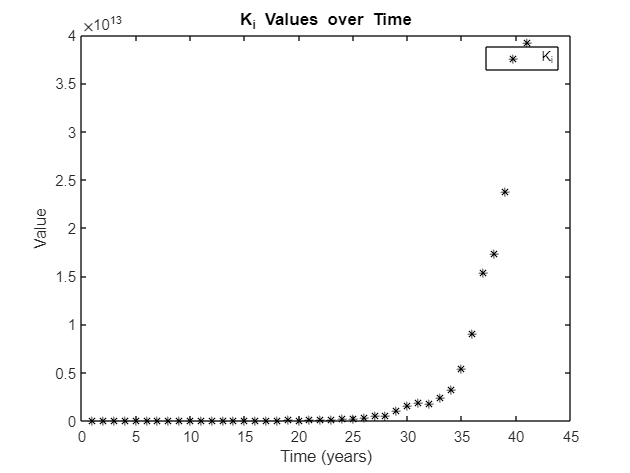



figure
plot(v1,KXI(:,2),'k*')

title('K_i Values over Time')
xlabel('Time (years)')
ylabel('Value')
legend('K_i');
saveas(gcf, "ki.png")